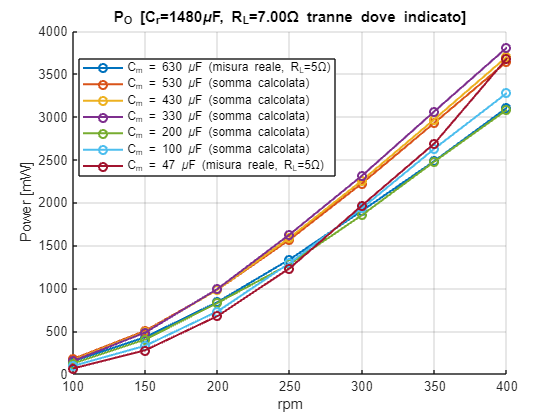


% Dati misurati (D1_f_sweep.csv, D2_f_sweep.csv):
% sweep di rpm per 7 valori fissi del condensatore di compensazione C_m,
% sommati sui due bridge FWR-Delta per ottenere la potenza totale e il rendimento.
% R_L = 7 Ohm fisso (stesso valore riportato in entrambi i CSV).
% NOTA: i CSV originali usano il punto "." come separatore delle migliaia (es. "1.147,796"
% mW); nell'export e' stato sostituito da una virgola, dando un formato a tre gruppi
% "1,147,796" che va decodificato come 1147.796 mW (i gruppi prima dell'ultimo
% costituiscono la parte intera, l'ultimo gruppo sono i millesimi).
% CORREZIONI (valori anomali di un ordine di grandezza rispetto alle celle vicine della
% stessa riga, stesso tipo di errore di virgola gia' visto nel C_sweep/R_sweep):
%   D1, rpm=200, C_m=530uF : Po  49.817  -> 498.17
%   D1, rpm=250, C_m=200uF : Pi 177.323  -> 1773.23
%   D2, rpm=400, C_m=630uF : Po 181.742  -> 1817.42
%
% Per C_m = 630 uF e C_m = 47 uF e' disponibile anche la misura reale con i due bridge
% gia' collegati in parallelo (D_1+2_f_sweep.csv, R_L = 5 Ohm, nessun dato di Pi): queste
% due colonne nel grafico di P_O usano la misura reale al posto della somma calcolata dei
% bridge singoli; le altre 5 colonne (530/430/330/200/100 uF) restano la somma calcolata
% a R_L = 7 Ohm. Il grafico di efficienza resta invariato (calcolato dai bridge singoli),
% perche' il file della misura in parallelo non contiene Pi.

C_r = 1480e-6;      % F - condensatore di filtro/raddrizzatore, fisso
R_L = 7;            % Ohm - carico fisso dei bridge singoli (le due curve "misura reale" sotto sono a R_L=5 Ohm)

rpm_plot = [100 150 200 250 300 350 400];
C_L_plot = [630 530 430 330 200 100 47]*1e-6;   % F
n_CL = numel(C_L_plot);
colors = lines(n_CL);

% Potenza totale = somma dei due bridge singoli, colonne = C_L_plot, righe = rpm_plot
P_real_tot_mW = [ ...
     180.078  174.988  162.732  152.033  122.758   94.025   44.058; ...
     510.993  504.859  491.896  484.650  403.460  330.115  200.065; ...
     978.613  983.821  983.860  993.712  829.777  731.293  507.253; ...
    1555.031 1570.307 1592.833 1630.697 1283.158 1296.169  982.594; ...
    2193.115 2226.615 2259.897 2316.580 1856.230 1937.356 1636.655; ...
    2875.278 2932.158 2973.314 3065.878 2479.616 2629.869 2525.935; ...
    3572.547 3644.024 3702.378 3808.189 3082.439 3278.090 3524.902];
P_real_tot = P_real_tot_mW/1000;

% Potenza reale misurata con i due bridge gia' in parallelo (D_1+2_f_sweep.csv, R_L=5 Ohm),
% disponibile solo per C_m = 630 uF (colonna 1) e C_m = 47 uF (colonna 7)
Po_meas_630_mW = [148.722 430.397 840.144 1339.088 1906.131 2485.999 3106.791];
Po_meas_47_mW  = [64.545  277.332 676.425 1236.093 1969.002 2691.710 3681.635];

P_real_tot(:,1) = Po_meas_630_mW/1000;   % sostituisce la colonna C_m=630uF con la misura reale
P_real_tot(:,n_CL) = Po_meas_47_mW/1000; % sostituisce la colonna C_m=47uF con la misura reale

% Rendimento di raddrizzamento eta_rec = P_O/P_I, stessa disposizione righe/colonne
% (invariato: calcolato dai bridge singoli, nessun dato Pi per la misura in parallelo)
eta_in = [ ...
    0.2931 0.3039 0.2674 0.2612 0.2625 0.2423 0.1748; ...
    0.3736 0.3904 0.3535 0.3518 0.3546 0.3303 0.2685; ...
    0.4196 0.4343 0.4056 0.4102 0.4114 0.3897 0.3336; ...
    0.4524 0.4639 0.4368 0.4467 0.4373 0.4332 0.3812; ...
    0.4764 0.4827 0.4645 0.4700 0.4644 0.4634 0.4202; ...
    0.4806 0.4970 0.4861 0.4886 0.4870 0.4871 0.4553; ...
    0.5074 0.5087 0.5011 0.5028 0.5042 0.5041 0.4831];

% PEE (Power Extraction Efficiency = P_real/P_matched) omessa per ora:
% manca il riferimento di potenza a carico adattato P_matched(rpm) (vedi f_sweep NVC).


% Grafico P_O ridotto alle sole due colonne con misura reale (bridge gia'
% in parallelo, R_L=5 Ohm): C_m piu' grande (630uF) e C_m piu' piccolo (47uF).
% Le 5 colonne intermedie (somma calcolata dei due bridge singoli) non
% vengono piu' plottate qui.
figure;
hold on;
plot(rpm_plot, P_real_tot(:,1)*1000, 'o-', 'LineWidth', 1.5, 'Color', colors(1,:));
plot(rpm_plot, P_real_tot(:,n_CL)*1000, 'o-', 'LineWidth', 1.5, 'Color', colors(n_CL,:));
grid on;
title(sprintf('P_O [C_r=%.0f\\muF, R_L=5\\Omega, misura reale]', C_r*1e6));
xlabel('rpm');
ylabel('Power [mW]');

legendEntries_Po = {sprintf('C_m = %.0f \\muF', C_L_plot(1)*1e6), sprintf('C_m = %.0f \\muF', C_L_plot(n_CL)*1e6)};
legend(legendEntries_Po, 'Location', 'best');
hold off;


%{
%%%PEE

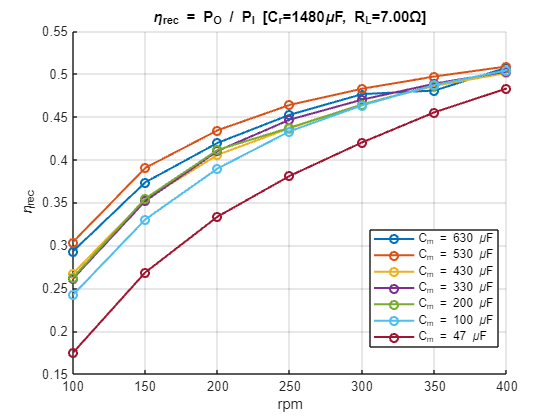

figure;
hold on;
for k = 1:n_CL
    plot(rpm_plot, Pee(:,k), 'o-', 'LineWidth', 1.5, 'Color', colors(k,:));
end
grid on;
title(sprintf('PEE = P_{Real} / P_{Matched} [C_r=%.0f\\muF, R_L=%.2f\\Omega]', C_r*1e6, R_L));
xlabel('rpm');
ylabel('PEE');

legendEntries = cell(1, n_CL);
for k = 1:n_CL
    legendEntries{k} = sprintf('C_m = %.0f \\muF', C_L_plot(k)*1e6);
end
legend(legendEntries, 'Location', 'best');
hold off;
%}


%%%efficiency
figure;
hold on;
for k = 1:n_CL
    plot(rpm_plot, eta_in(:,k), 'o-', 'LineWidth', 1.5, 'Color', colors(k,:));
end
grid on;
title(sprintf('\\eta_{rec} = P_{O} / P_{I} [C_r=%.0f\\muF, R_L=%.2f\\Omega]', C_r*1e6, R_L));
xlabel('rpm');
ylabel('\eta_{rec}');

legendEntries_eta = cell(1, n_CL);
for k = 1:n_CL
    legendEntries_eta{k} = sprintf('C_m = %.0f \\muF', C_L_plot(k)*1e6);
end
legend(legendEntries_eta, 'Location', 'best');
hold off;



% Sweep di frequenza dei singoli bridge D1/D2 (D1_f_sweep.csv, D2_f_sweep.csv),

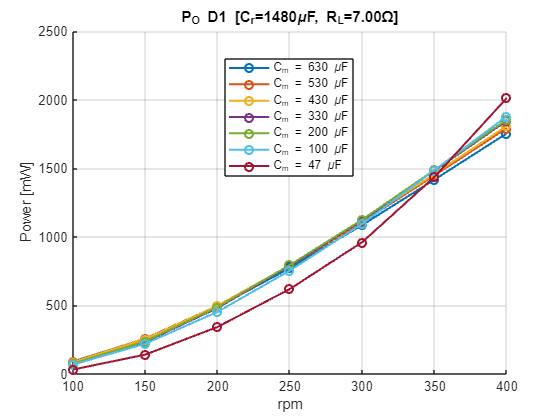

% un grafico ciascuno, a confronto con le curve sopra (somma calcolata / misura reale).
% R_L = 7 Ohm fisso per entrambi (stesso valore usato sopra per i bridge singoli).
% Include le stesse correzioni gia' applicate sopra (D1 rpm=200 C_m=530uF,
% D2 rpm=400 C_m=630uF).

P_b1_mW = [ ...
      91.667   88.954   86.351   74.488   75.617   68.668   32.563; ...
     257.219  258.497  254.876  235.105  239.059  220.965  141.412; ...
     489.275  498.170  498.813  481.632  488.176  453.682  343.338; ...
     772.779  787.392  792.395  789.868  795.289  754.696  620.218; ...
    1086.476 1107.738 1115.551 1118.834 1125.849 1095.556  961.865; ...
    1417.903 1448.029 1459.227 1482.964 1488.366 1486.717 1437.692; ...
    1755.127 1792.966 1808.817 1847.460 1854.898 1879.349 2013.089];

P_b2_mW = [ ...
      88.411   86.034   76.381   77.545   47.141   25.357   11.495; ...
     253.774  246.362  237.020  249.545  164.401  109.150   58.653; ...
     489.338  485.651  485.047  512.080  341.601  277.611  163.915; ...
     782.252  782.915  800.438  840.829  487.869  541.473  362.376; ...
    1106.639 1118.877 1144.346 1197.746  730.381  841.800  674.790; ...
    1457.375 1484.129 1514.087 1582.914  991.250 1143.152 1088.243; ...
    1817.420 1851.058 1893.561 1960.729 1227.541 1398.741 1511.813];

P_real_b1_f = P_b1_mW/1000;
P_real_b2_f = P_b2_mW/1000;

figure;
hold on;
for k = 1:n_CL
    plot(rpm_plot, P_real_b1_f(:,k)*1000, 'o-', 'LineWidth', 1.5, 'Color', colors(k,:));
end
grid on;
title(sprintf('P_O D1 [C_r=%.0f\\muF, R_L=%.2f\\Omega]', C_r*1e6, R_L));
xlabel('rpm');
ylabel('Power [mW]');
legendEntries = cell(1, n_CL);
for k = 1:n_CL
    legendEntries{k} = sprintf('C_m = %.0f \\muF', C_L_plot(k)*1e6);
end
legend(legendEntries, 'Location', 'best');
hold off;

figure;
hold on;
for k = 1:n_CL

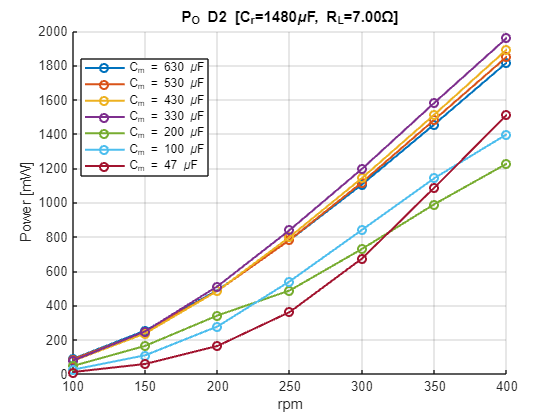

    plot(rpm_plot, P_real_b2_f(:,k)*1000, 'o-', 'LineWidth', 1.5, 'Color', colors(k,:));
end
grid on;
title(sprintf('P_O D2 [C_r=%.0f\\muF, R_L=%.2f\\Omega]', C_r*1e6, R_L));
xlabel('rpm');
ylabel('Power [mW]');
legendEntries = cell(1, n_CL);
for k = 1:n_CL
    legendEntries{k} = sprintf('C_m = %.0f \\muF', C_L_plot(k)*1e6);
end
legend(legendEntries, 'Location', 'best');
hold off;